Opgave 3 Reeksamen F15

% Opgave a
clc
clear

y = [0 57 95 141 182 230 285 351 418 491 567 646 712]'; % Nedbør
t = [0 31 59 90 120 151 181 212 243 273 304 334 365]'; % Dagsnummer

format shortE

n = length(t);

koeff = polyfit(t, y, n-1)';



T = table(koeff, t, y);
disp(T)

       koeff           t             y     
    ___________    __________    __________

    -6.9696e-24    0.0000e+00    0.0000e+00
     1.5001e-20    3.1000e+01    5.7000e+01
    -1.4240e-17    5.9000e+01    9.5000e+01
     7.8506e-15    9.0000e+01    1.4100e+02
    -2.7853e-12    1.2000e+02    1.8200e+02
     6.6575e-10    1.5100e+02    2.3000e+02
    -1.0901e-07    1.8100e+02    2.8500e+02
     1.2176e-05    2.1200e+02    3.5100e+02
    -9.0402e-04    2.4300e+02    4.1800e+02
     4.2183e-02    2.7300e+02    4.9100e+02
    -1.1051e+00    3.0400e+02    5.6700e+02
     1.3847e+01    3.3400e+02    6.4600e+02
     4.5609e-08    3.6500e+02    7.1200e+02




% der plottes for at se hvor godt fittet er

tlin = linspace(min(t), max(t))

tlin =             0   3.6869e+00   7.3737e+00   1.1061e+01   1.4747e+01   1.8434e+01   2.2121e+01   2.5808e+01   2.9495e+01   3.3182e+01   3.6869e+01   4.0556e+01   4.4242e+01   4.7929e+01   5.1616e+01   5.5303e+01   5.8990e+01   6.2677e+01   6.6364e+01   7.0051e+01   7.3737e+01   7.7424e+01   8.1111e+01   8.4798e+01   8.8485e+01   9.2172e+01   9.5859e+01   9.9545e+01   1.0323e+02   1.0692e+02   1.1061e+02   1.1429e+02   1.1798e+02   1.2167e+02   1.2535e+02   1.2904e+02   1.3273e+02   1.3641e+02   1.4010e+02   1.4379e+02   1.4747e+02   1.5116e+02   1.5485e+02   1.5854e+02   1.6222e+02   1.6591e+02   1.6960e+02   1.7328e+02   1.7697e+02   1.8066e+02


ys = polyval(koeff, tlin)

ys =    4.5609e-08   3.7984e+01   5.6503e+01   6.3334e+01   6.3858e+01   6.1653e+01   5.8970e+01   5.7106e+01   5.6695e+01   5.7929e+01   6.0725e+01   6.4847e+01   6.9991e+01   7.5841e+01   8.2108e+01   8.8551e+01   9.4983e+01   1.0127e+02   1.0734e+02   1.1315e+02   1.1870e+02   1.2402e+02   1.2914e+02   1.3412e+02   1.3901e+02   1.4385e+02   1.4869e+02   1.5357e+02   1.5850e+02   1.6352e+02   1.6861e+02   1.7380e+02   1.7907e+02   1.8443e+02   1.8987e+02   1.9539e+02   2.0099e+02   2.0666e+02   2.1241e+02   2.1826e+02   2.2421e+02   2.3027e+02   2.3646e+02   2.4279e+02   2.4928e+02   2.5594e+02   2.6277e+02   2.6977e+02   2.7696e+02   2.8431e+02


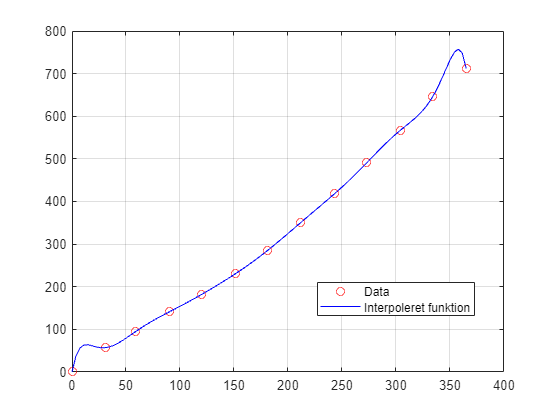


plot(t,y, 'ro', 'DisplayName', 'Data'), grid("on")
hold on
plot(tlin, ys,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off

%Interp1 bruges
format shortG

int100 = interp1(t,y,100)

int100 =        154.67


Altså 154,7mm

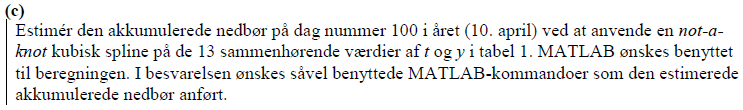

spl100 = spline(t,y,100) % spline interpolerer mellem værdierne

spl100 =        154.87


154.87mm

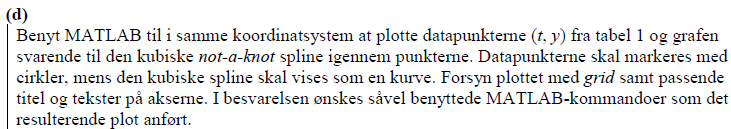

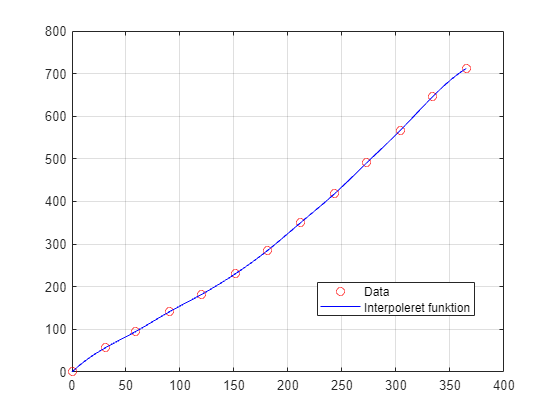

spl_func = spline(t,y,tlin);

plot(t,y, 'ro', 'DisplayName', 'Data'), grid("on")
hold on
plot(tlin, spl_func,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off

afv = (spl100 - int100)/spl100 * 100

afv =       0.13316



% Det ses altså at der kun er en afvigelse på 0.13% - så på den front er
% der ingen foretrukken metode. Dog er not-a-knot nok bedre, eftersom den
% giver en mere ren kurve.


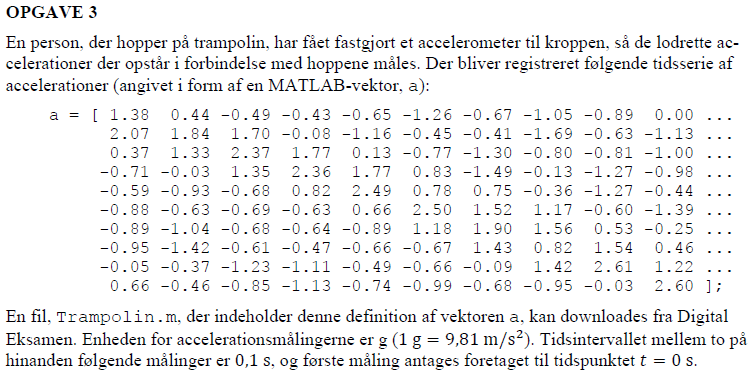

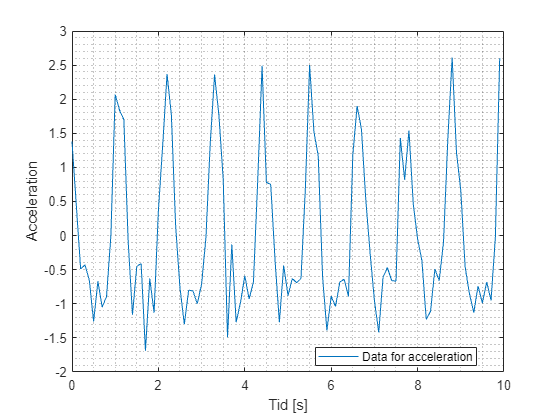

clc
clear
format short
accel = [ 1.38 0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89 0.00 ...
2.07 1.84 1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...
0.37 1.33 2.37 1.77 0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...
-0.71 -0.03 1.35 2.36 1.77 0.83 -1.49 -0.13 -1.27 -0.98 ...
-0.59 -0.93 -0.68 0.82 2.49 0.78 0.75 -0.36 -1.27 -0.44 ...
-0.88 -0.63 -0.69 -0.63 0.66 2.50 1.52 1.17 -0.60 -1.39 ...
-0.89 -1.04 -0.68 -0.64 -0.89 1.18 1.90 1.56 0.53 -0.25 ...
-0.95 -1.42 -0.61 -0.47 -0.66 -0.67 1.43 0.82 1.54 0.46 ...
-0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09 1.42 2.61 1.22 ...
0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03 2.60 ];

tid = 0:0.1:(length(accel)/10-0.1); % den rigtige dimension for tiden laves


plot(tid, accel,'DisplayName','Data for acceleration')
legend(Location="best"), grid("minor"), xlabel("Tid [s]"), ylabel("Acceleration")


n_top = 9;
t = 10;
f = n_top/t

f = 0.9000


% Frekvensen er altsp 0.9hz


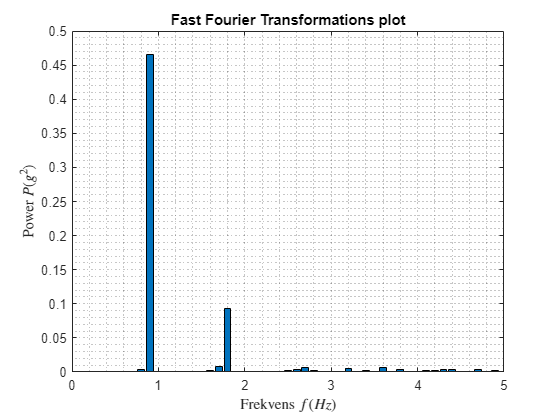

dt = 0.1;                       % Samplingsinterval (s)
n = length(accel);                  % Antal samplinger % her vælges alt data som sample
T = n*dt;                       % Signallængde (s) % Tiden det tager at køre smplet igennem
A = fft(accel)/n;                   % FFT af a (mm)
fs = 1/dt;                      % Samplingsfrekvens (Hz) %Frekvensen hvormed der tages sampels
fmax = fs/2;                    % Maks frekvens (Hz)
df = 1/T;                       % Frekvensstep (Hz)
f = (0:n-1)*df;                 % Frekvensvektor (Hz) % alle frekvensskridt der gennemgåes
P = real(A).^2 + imag(A).^2;    % Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive
bar(f,P);                       % Plot af powerspektrum %plottes som barplot for bedre overskuelighed
xlim([0 fmax]);                 % Afgræns frekvensakse % så der kun ses på et område der ikke gentager en frekvens

%Plot

title('Fast Fourier Transformations plot')
xlabel('Frekvens $f(Hz)$', 'interpreter', 'latex')
ylabel('Power $P(g^2)$', 'interpreter', 'latex')
grid('minor')



max_F = find(P==max(P))

max_F =     10    92



% Her vælges første tal da andet tal blot af en gentagelse af frekvensen
% Frekvensen af det stærkeste signal bliver
f_strong = f(10)

f_strong = 0.9000

% Altså 0.9Hz